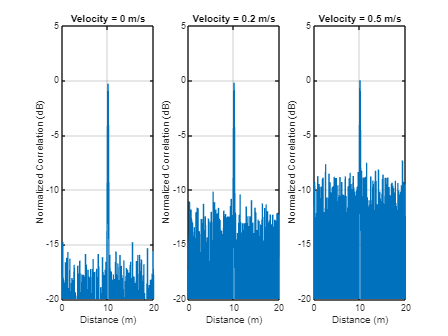

% Define simulation parameters
distances = linspace(0, 20, 2000); % Distance vector from 0 to 20 meters
target_dist = 10; % Target at 10 meters
power_backscattered = 1.5e-9; % Power of backscattered signal in watts (1.5 nW)
velocities = [0, 0.2, 0.5]; % Velocities of the target in m/s

% Base noise level corresponding to the lowest velocity
base_noise_level = power_backscattered / 100; % Arbitrary choice to simulate a low SNR

% Initialize array to hold all signal values
signal = zeros(length(distances), length(velocities));

% Generate signals for different target velocities
for i = 1:length(velocities)
    % Adjust the noise level based on velocity to simulate DFS effect
    noise_level = base_noise_level * (1 + velocities(i) * 10); % Increasing noise with velocity
    
    % Backscattered signal (Gaussian peak)
    backscattered_signal = power_backscattered * exp(-((distances - target_dist).^2) / (0.1^2));
    
    % Add noise to the signal
    noisy_signal = backscattered_signal + noise_level * randn(size(backscattered_signal));
    
    % Make sure the signal stays above the noise floor
    noisy_signal = max(noisy_signal, base_noise_level);
    
    % Store the noisy signal
    signal(:, i) = noisy_signal;
end

% Plot the results
figure;
for i = 1:length(velocities)
    subplot(1, 3, i);
    % Convert to dB scale for plotting
    signal_db = 10 * log10(signal(:, i) / max(signal(:)));
    plot(distances, signal_db);
    title(['Velocity = ' num2str(velocities(i)) ' m/s']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (dB)');
    ylim([-20 5]); % Adjust y-limits to match the provided figure
    grid on;
end

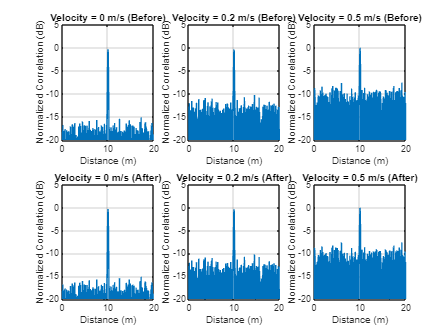

% Define simulation parameters
distances = linspace(0, 20, 2000); % Distance vector from 0 to 20 meters
target_dist = 10; % Target at 10 meters
power_backscattered = 1.5e-9; % Power of backscattered signal in watts (1.5 nW)
velocities = [0, 0.2, 0.5]; % Velocities of the target in m/s
lambda = 1550e-9; % Wavelength of the LiDAR in meters (1550 nm)

% Base noise level corresponding to the lowest velocity
base_noise_level = power_backscattered / 100; % Arbitrary choice to simulate a low SNR

% Initialize array to hold all signal values
signal = zeros(length(distances), length(velocities));
compensated_signal = signal; % Initialize compensated signal array

% Generate signals for different target velocities and apply Doppler compensation
for i = 1:length(velocities)
    % Simulate the Doppler effect by shifting the frequency
    frequency_shift = (velocities(i) / lambda) * 2; % Doppler shift (f = 2 * v / lambda)
    
    % Adjust the noise level based on velocity to simulate DFS effect
    noise_level = base_noise_level * (1 + velocities(i) * 10); % Increasing noise with velocity
    
    % Backscattered signal (Gaussian peak)
    backscattered_signal = power_backscattered * exp(-((distances - target_dist).^2) / (0.1^2));
    
    % Simulate Doppler effect on backscattered signal
    doppler_signal = backscattered_signal .* exp(1j * 2 * pi * frequency_shift * distances);
    
    % Add noise to the signal
    noisy_signal = abs(doppler_signal) + noise_level * randn(size(backscattered_signal));
    
    % Make sure the signal stays above the noise floor
    noisy_signal = max(noisy_signal, base_noise_level);
    
    % Doppler compensation
    compensated_signal(:, i) = noisy_signal .* exp(-1j * 2 * pi * frequency_shift * distances);
    
    % Store the noisy signal
    signal(:, i) = noisy_signal;
end

% Plot the results before and after Doppler compensation
figure;
for i = 1:length(velocities)
    subplot(2, 3, i);
    % Convert to dB scale for plotting
    signal_db = 10 * log10(signal(:, i) / max(signal(:)));
    plot(distances, signal_db);
    title(['Velocity = ' num2str(velocities(i)) ' m/s (Before)']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (dB)');
    ylim([-20 5]); % Adjust y-limits to match the provided figure
    grid on;
    
    subplot(2, 3, i+length(velocities));
    % Convert to dB scale for plotting
    compensated_signal_db = 10 * log10(abs(compensated_signal(:, i)) / max(abs(compensated_signal(:))));
    plot(distances, compensated_signal_db);
    title(['Velocity = ' num2str(velocities(i)) ' m/s (After)']);
    xlabel('Distance (m)');
    ylabel('Normalized Correlation (dB)');
    ylim([-20 5]); % Adjust y-limits to match the provided figure
    grid on;
end